# COVID in MA analyzer

## Introduction and citations

### Data sources

I'm using the wiki compilation at [https://en.wikipedia.org/wiki/2020_coronavirus_pandemic_in_Massachusetts](https://en.wikipedia.org/wiki/2020_coronavirus_pandemic_in_Massachusetts) which gives confirmed cases of COVID-19 in Masachusetts, acording ultimately to the daily updates from the MA Dept of Public Health, such as [https://www.mass.gov/doc/covid-19-cases-in-massachusetts-as-of-march-28-2020/download](https://www.mass.gov/doc/covid-19-cases-in-massachusetts-as-of-march-28-2020/download) .

### Subsidiary factoids:

#### Population of Boston:   

pop_yr=[2010, 2017];
pop_pp=[620702,685094];
pop_2020_bos=diff(pop_pp)/diff(pop_yr)*3+pop_pp(2)

pop_2020_bos = 7.1269e+05

#### Population of Massachusetts:   

pop_yr=[2005, 2018];
pop_pp=[6.454e6,6.902e6];
pop_2020_ma=diff(pop_pp)/diff(pop_yr)*2+pop_pp(2)

pop_2020_ma = 6.9709e+06

### Intent

Just to have an idea of when we should see a peak.

### Data sets and structure

Data are given in the table Cov_Ma. 

Cov_Ma.Properties.VariableNames

ans = 1×12 cell array
    {'Days_since_Mar_10'}    {'Cases'}    {'Date'}    {'Cases_change'}    {'Cases_growth'}    {'Tests'}    {'Tests_change'}    {'Tests_growth'}    {'Deaths'}    {'Deaths_change'}    {'Deaths_growth'}    {'Growth'}

## Just the facts, ma'am

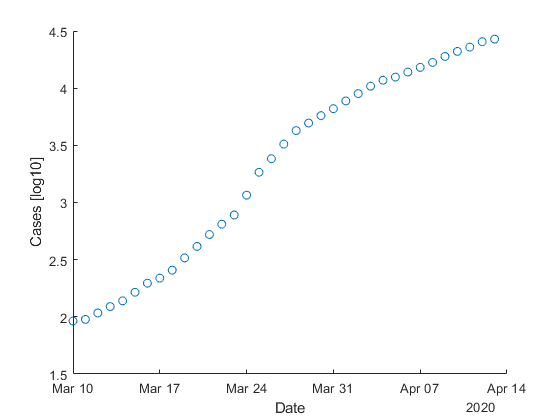

figure
scatter(Cov_Ma.Date, log10(Cov_Ma.Cases))
ylabel('Cases [log10]')
xlabel('Date')

## Fitting the data to a logistic curve

The logistic curve is given by 


$$m_i=\frac{k_i}{1+e^{-(t-t_0) \cdot \gamma}}$$


where $m_i$ is a measure of COVID (I use identified cases and identified deaths), $t$ is th enumber of days since March 10 (a reasonble measure of when community spreading started), $t_0$ is the midpoint of the growth (measured in days since March 10), and $\gamma$ is a constant related to growth rate.

One must initialize the vector of constants with initial conditions to begin the minimization that finds the best-fitting array of constants.These are determined by trial and error. Good practice is to use a variety of IC to make sure the solution i srobust. The ICs are in array $beta0_i$. MATLAB makes fitting the model pretty easy. 

### FIts

#### Cases

modelfun_c = @(b,x)b(1)./(1+exp(-(x-b(2))*b(3)))

modelfun_c = function_handle with value:
    @(b,x)b(1)./(1+exp(-(x-b(2))*b(3)))

beta0_c = [40000 50 0.05];
mdl_c = fitnlm(Cov_Ma.Days_since_Mar_10,Cov_Ma.Cases,modelfun_c,beta0_c)

mdl_c = Nonlinear regression model:
    y ~ F(b,x)

Estimated Coefficients:
          Estimate       SE        tStat       pValue  
          ________    _________    ______    __________
    b1      39781        2635.2    15.096    4.1547e-16
    b2      30.24       0.76863    39.343    1.1341e-28
    b3    0.18307     0.0079304    23.085    1.6162e-21

Number of observations: 35, Error degrees of freedom: 32
Root Mean Squared Error: 511
R-Squared: 0.996,  Adjusted R-Squared 0.996
F-statistic vs. zero model: 5.2e+03, p-value = 4.45e-43

#### Deaths

modelfun_d = @(b,x)b(1)./(1+exp(-(x-b(2))*b(3)))

modelfun_d = function_handle with value:
    @(b,x)b(1)./(1+exp(-(x-b(2))*b(3)))

beta0_d = [100 20 0.222];
mdl_d = fitnlm(Cov_Ma.Days_since_Mar_10,Cov_Ma.Deaths,modelfun_d,beta0_d)

mdl_d = Nonlinear regression model:
    y ~ F(b,x)

Estimated Coefficients:
          Estimate       SE        tStat       pValue  
          ________    _________    ______    __________
    b1     1495.7        114.67    13.044    2.3612e-14
    b2     32.849       0.63631    51.625    2.1698e-32
    b3    0.23616     0.0089026    26.527    2.3453e-23

Number of observations: 35, Error degrees of freedom: 32
Root Mean Squared Error: 11.7
R-Squared: 0.998,  Adjusted R-Squared 0.998
F-statistic vs. zero model: 7.12e+03, p-value = 2.91e-45

### Predictions

Pred_window=21;
Pred_days=0:max(Cov_Ma.Days_since_Mar_10)+Pred_window;
Pred_dates=(min(Cov_Ma.Date):days(1):max(Cov_Ma.Date)+days(Pred_window))';
[Cov_Ma_Pred.cases, Cov_Ma_Pred.casesci]=predict(mdl_c,Pred_days','Prediction','observation');
[Cov_Ma_Pred.deaths, Cov_Ma_Pred.deathsci]=predict(mdl_d,Pred_days','Prediction','observation');

### Graph the data and the models up

#### Cases

figure
plot(Pred_dates,Cov_Ma_Pred.cases,'--bs')
hold

Current plot held


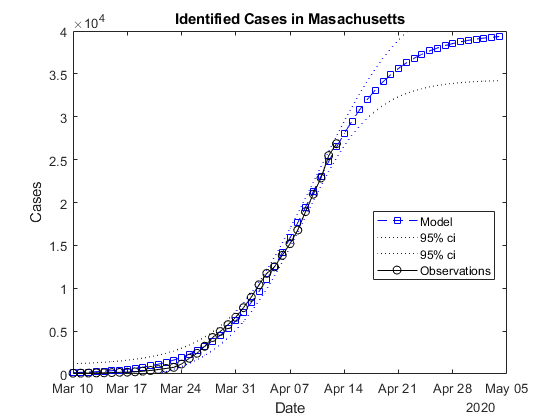

plot(Pred_dates,Cov_Ma_Pred.casesci(:,1),':b')
plot(Pred_dates,Cov_Ma_Pred.casesci(:,2),':b')
plot(Cov_Ma.Date,Cov_Ma.Cases, '-ko')
ylabel('Cases')
xlabel('Date')
ylim([0,40000])
title('Identified Cases in Masachusetts')
legend('Model','95% ci','95% ci','Observations', 'location', 'best')

#### Deaths

figure
plot(Pred_dates,Cov_Ma_Pred.deaths,'--ms')
hold

Current plot held


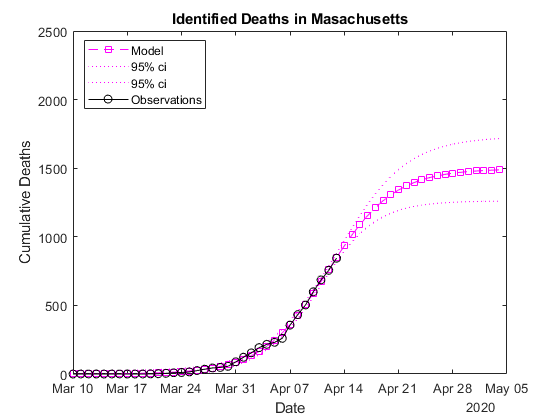

plot(Pred_dates,Cov_Ma_Pred.deathsci(:,1),':m')
plot(Pred_dates,Cov_Ma_Pred.deathsci(:,2),':m')
plot(Cov_Ma.Date,Cov_Ma.Deaths,'-ko')
ylabel('Cumulative Deaths')
xlabel('Date')
ylim([0,2500])
title('Identified Deaths in Masachusetts')
legend('Model','95% ci','95% ci','Observations', 'location', 'best')

## When are the peaks?

Take the differences in the cumulative graphs and plot them up to see the peaks.

figure
yyaxis right
plot(Pred_dates(2:end),diff(Cov_Ma_Pred.deaths),'Color', [.94 .5 .5], 'LineStyle','-', 'Marker','s')
hold

Current plot held


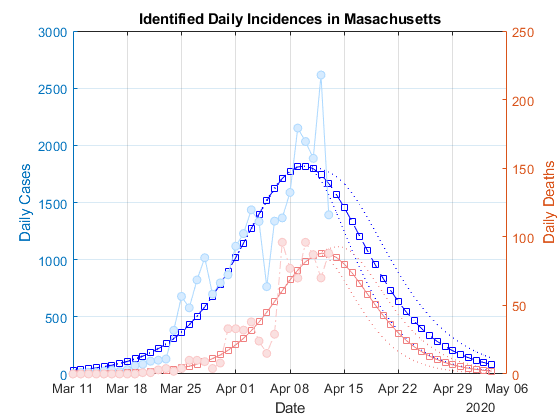

grid
plot(Pred_dates(2:end),diff(Cov_Ma_Pred.deathsci(:,1)),'Color', [.94 .5 .5], 'LineStyle',':')
plot(Pred_dates(2:end),diff(Cov_Ma_Pred.deathsci(:,2)),'Color', [.94 .5 .5], 'LineStyle',':')
plot(Cov_Ma.Date(2:end),diff(Cov_Ma.Deaths),'Color', [.98 .78 .78], 'MarkerFaceColor',[.98 .88 .88], 'Marker', 'o')
ylabel('Daily Deaths')
xlabel('Date')
ylim([0,250])
title('Identified Daily Incidences in Masachusetts')
%legend('Model','95% ci','95% ci','Observations', 'location', 'best')
yyaxis left
plot(Pred_dates(2:end),diff(Cov_Ma_Pred.cases),'--bs')
plot(Pred_dates(2:end),diff(Cov_Ma_Pred.casesci(:,1)),':b')
plot(Pred_dates(2:end),diff(Cov_Ma_Pred.casesci(:,2)),':b')
plot(Cov_Ma.Date(2:end),diff(Cov_Ma.Cases),'Color', [.68 .85 1], 'MarkerFaceColor', [.84 .92 1], 'Marker', 'o')
ylabel('Daily Cases')

%xlabel('Date')
%ylim([0,50])
%title('Identified Daily Incidences in Masachusetts')
%legend('Model','95% ci','95% ci','Observations', 'location', 'best')

## Using previous results to predict the short-term future

#### Just the  numbers

figure
yyaxis left
plot(beta0time.Date,beta0time.k_cases,'-bs')
ylabel('Estimated Maximum Cases')
xlabel('Date')
ylim([0,40000])
title('Evolution of Models: no convergence suggests...a bad model')
hold

Current plot held


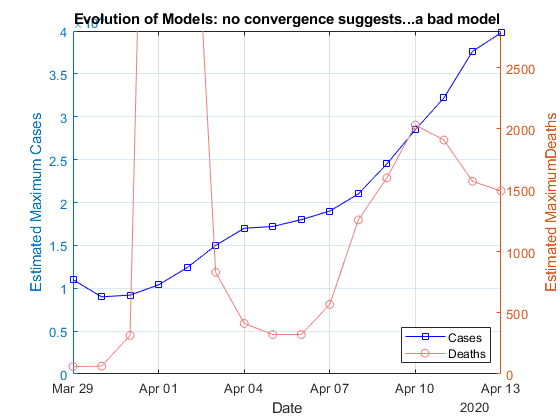

grid
yyaxis right
plot(beta0time.Date,beta0time.k_deaths,'Color', [.94 .5 .5], 'LineStyle','-', 'Marker','o')
ylabel('Estimated MaximumDeaths')
xlabel('Date')
ylim([0,2800])

legend('Cases', 'Deaths', 'location', 'southeast')

#### Ratio: death rate, 

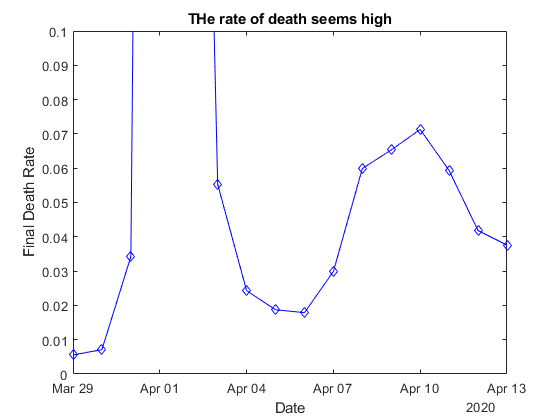

figure
plot(beta0time.Date,beta0time.k_deaths./beta0time.k_cases, '-bd')
ylabel('Final Death Rate')
xlabel('Date')
ylim([0,0.1])
title('THe rate of death seems high')

This high rate is most likely due to unidentified cases, which has been typical. Assume that the death rte in Massachusetts has been ~1.6%, we can identify the total case load: